# Spectral Sieve Algorithm

Given a Hamiltonian    $H_s \cong \sum_{j} \lambda_j |\phi_j \rangle \langle \phi_k |$ ,  interval $\Lambda = (\Lambda_0, \Lambda_1)$, and precision parameter $\epsilon$,

Map $H_s$ to a Hamiltonian                               $H =  H_s \otimes I_A + \sum_{j=1}^{m} \chi_j   \otimes a_j^{\dagger} +  \chi_j^{\dagger}  \otimes a_j$

where $\chi = \sum_{k=1}^{l} e^{-iH t_k} X_k$ and approximates the operator $\sum_{j,k} \hat{f}(\lambda_j) x_{j,k}  | \phi_j \rangle \langle \phi_k|$

with $X_k = X f(t_k)$, and $t_k$ associated with the quadrature rules.

(other generalisation is to use $\chi = \sum_{k=1}^{l} e^{-iH t_k} X_ke^{iH t_k}$ to approximate  $\sum_{j,k} \hat{f}(\lambda_j-\lambda_k) x_{j,k}  | \phi_j \rangle \langle \phi_k|,$ (operator fourier transform))

The Algorithm then repeatedly applies, the map 

                                                                  
$$E(\rho_j) =  Tr_A[ e^{iH} (\rho \otimes 0\rangle\langle0 |)]$$
 

while choosing random operators X to cause a perturbation to the system, to ideally move towards the desired eigenspace or invariant. For generic choces of efficiently impementable X, this map converges. The rate of convergence is to be detailed out. 

In constras to the metropolis algorithm, this is more Las Vegas styled, in the sense that nothing bad ever happes, but sometimes good thigs happen. Given enough time, the state moves to the desired eigensubspace, and is like a adiabatic/disipative algorithm in that sense

In the implementation we only need the approximate map, and it should be possible to also check if a $\delta$-approximate map suffices to get a $\epsilon \sim \delta^{?}$ close to the desired subspace in $poly(n, \frac{1}{\epsilon})$ iterations of a generic/some X. 

The cost of getting $\delta$-approximation map as a unitary circuit needs to be worked out. Using a combination of Newton-Cotes with Gauss-Hermite quadrature, BCH expansion, and interplay between 1 norm and sup norm,  $poly(n,\delta)$ cost per iteration, in the asymptotic sense may be obtained. 

Here in, using $f(t) = (e^{-i\Lambda_0 t} - e^{-i \Lambda_1t}) / (it)$  , with  $\hat{f}(\lambda) = 0$ when $\lambda  \notin \Lambda$, 1 otherwise, but may replace with other window functions

## Parameters

clc; clf;clear
n = 4; N=2^n;       % number and dimension of qubits
L0 = 0.2;
L1 = 0.4;

m = 1; M=2^m;       % number of ancillary qubits

Collisions = 1000;

lambda = 0.3;
time = 0.5;


normalisation = 1;  %
a = [0 1; 0 0];     % anhilation 

## Setting $H_s$

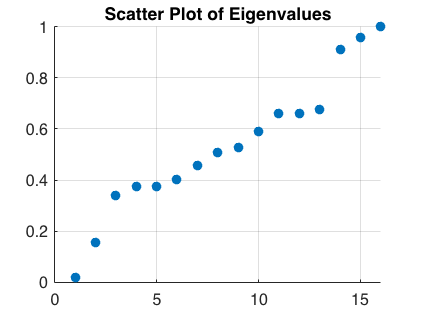

%
Hs = diag(1:N);               % A very nice H -- Diagnoal
Hs = diag(sort(rand(1,N)));         % A random H -- Diagnoal 
Hs= Hs/norm(Hs);              % normalise wlog
%Hs = [1 0; 0 0.1];
[V, D] = eig(Hs);             % H = V*D*V'

%% VIEW EIGENVALUE DISTRIBUTION
figure;
scatter(1:N, real(diag(D)), 'filled');  
title('Scatter Plot of Eigenvalues');
grid on;

## Visualsing $f$

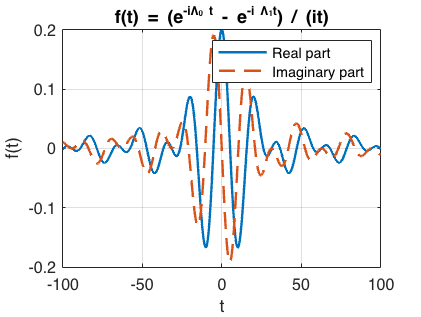

% Parameters
dt = 0.11;
t_values = -100:dt:100;

% f(t)
ff = zeros(size(t_values));
for k = 1:length(t_values)
    t = t_values(k);
    ff(k) = f(L0, L1, t);
end

% Plot f(t)
figure;
plot(t_values, real(ff), 'LineWidth', 1.5); hold on;
plot(t_values, imag(ff), '--', 'LineWidth', 1.5);
xlabel('t');
ylabel('f(t)');
legend('Real part', 'Imaginary part');
title('f(t) = (e^{-i\Lambda_0 t} - e^{-i \Lambda_1t}) / (it)');
grid on;


% % % %  Fourier Transform of f(t)
% Y = (fft(ff)); % ??????????????????????????????????????????????????
% frequencies = linspace(-pi, pi, length(t_values)); % Frequency axis
% 
% % Plot Fourier transform of f(t)
% figure;
% plot(frequencies, abs(Y), 'LineWidth', 1.5);
% xlabel('Frequency');
% ylabel('|Y(\omega)|');
% title('Fourier Transform of y(t)');
% grid on;

## Doing the map

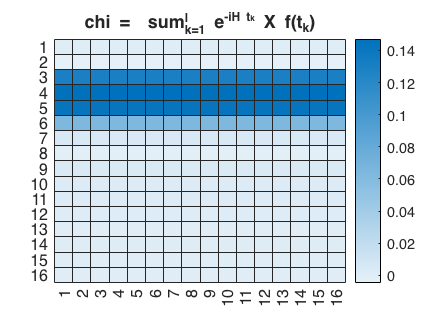

Perturbation  =  ones(N,N);           % Make this V'*Pertubration*V' in the basis of H; or just randomly
Chi = XX(Hs,Perturbation,L0,L1);
% Viewing the Chi
figure; heatmap(real(Chi), Title="chi =  sum_{k=1}^{l} e^{-iH t_k} X f(t_k)");

H = Make_H(time*Hs, time*lambda*Chi);
%figure; heatmap(real(H));

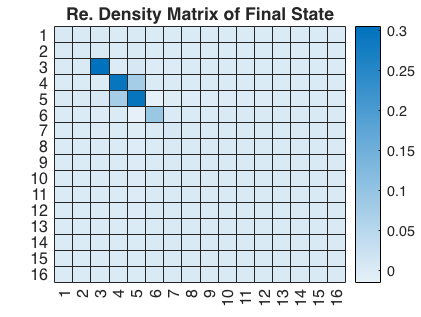

%Collisions = 10;                     % Number of Collisions
z0 = [1 0; 0 0];
state = eye(N)/N;                     % Initial State
state = zeros(N,N); state(1,1)=1;
energy = zeros(1,Collisions);
overlap = zeros(N,Collisions);

for j=1:Collisions
    % update state with map
    new_state = expm(1i*H)*kron(state,z0)*expm(-1i*H);
    state = partial_trace(new_state, N, M*N);
    % record overlaps with all eigenvectors
     VrhoVp = V*state*V';
     for k=1:N
         overlap(k,j) = VrhoVp(k,k);
     end
    energy(j) = trace(Hs*state);
end

%trace(state)
%norm(state-state')
%eig(state)             %% CHECKED valid quantum state!
figure; heatmap(real(state),Title="Re. Density Matrix of Final State")

## Visualisations

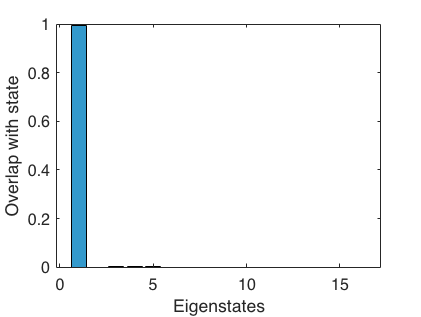

% figure; plot(overlap)
% figure; plot(energy)
bar(real(overlap(:,1)), 'FaceColor', [0.2, 0.6, 0.8])
xlabel('Eigenstates')
ylabel('Overlap with state')

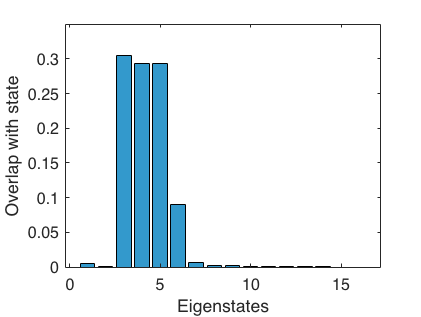

bar(real(overlap(:,Collisions)), 'FaceColor', [0.2, 0.6, 0.8])
xlabel('Eigenstates')
ylabel('Overlap with state')

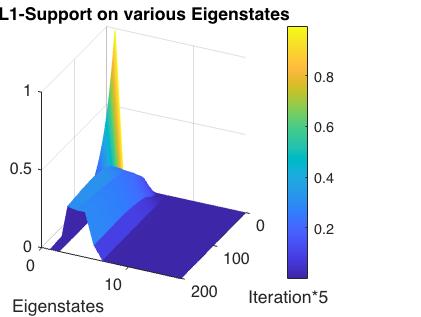



mesh(abs(overlap(:,1:5:1000)))
colorbar
title('L1-Support on various Eigenstates')
ylabel('Eigenstates')
xlabel('Iteration*5')
view([115 25])

### Movies 

% % How we got to the final state -- Create a movie of overlaps
% % UNCOMENT THIS TO MOVIE
% % Create a figure for the movie
% fig = figure;
% set(fig, 'Position', [100, 100, 800, 600]);
% 
% % Preallocate structure to store frames for the movie
% frames(Collisions) = struct('cdata', [], 'colormap', []);
% 
% % Generate bar plots and capture frames
% for t = 1:Collisions
%     % Create a bar plot of overlaps at time step t
%     bar(real(overlap(t, :)), 'FaceColor', [0.2, 0.6, 0.8])
%     ylim([0 1]);  % Set y-axis limits to visualize overlaps clearly
%     xlabel('Eigenstate Index');
%     ylabel('Overlap');
%     title(['Overlap at Collision ', num2str(t)]);
%     grid on;
%     
%     % Capture the current frame for the movie
%     frames(t) = getframe(fig);
%     
%     % Pause briefly to allow the figure to render
%     pause(0.05);  % You can adjust the pause duration for a smoother or faster animation
% end
% % Create the movie
% v = VideoWriter('overlap_movie.mp4','MPEG-4');  % Create a VideoWriter object
% v.FrameRate = 30;  % Set the frame rate for the video
% open(v);
% writeVideo(v, frames);  % Write the captured frames to the video file
% close(v);
% 
% % Optionally, you can replay the movie in the figure
% %implay('overlap_movie.mp4');
% movie(fig, frames, 1, v.FrameRate);

## Function to construct H

Map it to a Hamiltonian $H = I \otimes H_s + \sum_{j=1}^{m} a_j^{\dagger} \otimes \chi_j + a_j \otimes \chi_j^{\dagger}$

function H = Make_H(Hs, Proj) 
%% Input (Hs,X), where Hs is N*N matrix, Proj is a  N*N matrix
%% Outpits I*Hs + a'*XX + a*XX'                    % M=2 now
    M=2;
    a= [0 1; 0 0];
    H1 = kron(Hs,eye(M));
    H2 = kron(Proj,a');
    H2 = H2+H2';
    H = H1+H2;      
    H = H/norm(H);
end

## Function $\chi = \sum_{k=1}^{l} e^{-iH t_k} X_k f(t_k)$ 

function P = XX(Hs,X,L0,L1) 
%Input X, where X is a N*N matrix, 
%% Output: Chi above, 
    Proj = zeros(size(X));
    dt = 0.11;                 %time step
    for t= -100:dt: 100   
        Proj = Proj+expm(1i*Hs*t)* X *((exp(-1i * L0 * t) - exp(-1i * L1 * t)) / (1i * t));
    end
    P = Proj/norm(Proj);
end

## Function $f = \frac{e^{-i\Lambda_0t}- e^{-i\Lambda_1t}}{it}$ 

function F = f(L0, L1, t)
    % Compute f(L0, L1, t)
    if t == 0
        t=0.000001
    end
    F = (exp(-1i * L0 * t) - exp(-1i * L1 * t)) / (1i * t);
end

### Partial Trace

function rho_A = partial_trace(rho, dim_A, dim_total)
%   Author: ???
%   Inputs:
%       rho: The density matrix of the composite system
%       dim_A: The dimension of subsystem A
%       dim_total: The total dimension of the composite system
%
%   Output:
%       rho_A: The reduced density matrix for subsystem A

    dim_B = dim_total / dim_A;  % Dimension of subsystem B
    rho_A = zeros(dim_A);  % Initialize rho_A

    % Perform the partial trace operation
    for i = 1:dim_A
        for j = 1:dim_A
            submatrix = rho((i-1)*dim_B+1:i*dim_B, (j-1)*dim_B+1:j*dim_B);
            rho_A(i, j) = trace(submatrix);
        end
    end
end